%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%DATA PRE PROCESSING (GET SIGNAL)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Fs = 25600

Fs = 25600

N = 768000 %Number of Samples 

N = 768000

f = 0:Fs/N:Fs/2

f = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Healthy Machine Variables 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%NO LOAD
nlgridcurrent = noloadhealthyG.Ia(1:N);
nlgridvibration = noloadhealthyG.IMY_Radial(1:N); 
nlinvertercurrent = noloadhealthyI.Ia(1:N); 
nlinvertervibration = noloadhealthyI.IMY_Radial(1:N);

%LOADED 
gridcurrent = loadhealthyG.Ia(1:N);
gridvibration = loadhealthyG.IMY_Radial(1:N); 
invertercurrent = loadhealthyI.Ia(1:N); 
invertervibration = loadhealthyI.IMY_Radial(1:N);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Stator Winding Fault Variables 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%NO LOAD
%Grid-Fed
gridcurrent_fault1_GNL = noload2interturnG.Ia(1:N);
gridvibration_fault1_GNL = noload2interturnG.IMY_Radial(1:N);

%Inverter-Fed
invertercurrent_fault1_INL1 = noload2interturnI.Ia(1:N); 
invertervibration_fault1_INL1 = noload2interturnI.IMY_Radial(1:N);
invertercurrent_fault1_INL2 = noload4interturnI.Ia(1:N); 
invertervibration_fault1_INL2 = noload4interturnI.IMY_Radial(1:N); 

%%LOADED
%Grid-Fed
gridcurrent_fault1_GL1 = load2interturnG.Ia(1:N); 
gridvibration_fault1_GL1 = load2interturnG.IMY_Radial(1:N); 

%Inverter-Fed
invertercurrent_fault1_IL1 = load2interturnI.Ia(1:N); 
invertervibration_fault1_IL1 = load2interturnI.IMY_Radial(1:N); 
invertercurrent2_fault1_IL2= load4interturnI.Ia(1:N); 
invertervibration2_fault1_IL2 = load4interturnI.IMY_Radial(1:N); 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Broken Rotor Bar Fault Variables 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
gridcurrent_fault2_GNL = noloadbrokenG.Ia(1:N);
gridvibration_fault2_GNL = noloadbrokenG.IMY_Radial(1:N);
invertercurrent_fault2_INL = noloadbrokenI.Ia(1:N);
invertervibration_fault2_INL = noloadbrokenI.IMY_Radial(1:N);

gridcurrent_fault2_GL = loadbrokenG.Ia(1:N);
gridvibration_fault2_GL = loadbrokenG.IMY_Radial(1:N);
invertercurrent_fault2_IL = loadbrokenI.Ia(1:N);
invertervibration_fault2_IL = loadbrokenI.IMY_Radial(1:N);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% FREQUENCY-DOMAIN ANALYSIS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Vibration Monitoring Grid-Fed Supply Stator Winding Faults
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%
%2 shorted turns 
%%%%%%%%%%%%%%%%
%%NO LOAD
%Healthy No Load
subplot(2,1,1);
nfft = 2^nextpow2(length(nlgridvibration));
pxx = abs(fft(nlgridvibration,nfft)).^2/length(nlgridvibration)/Fs;
maximum = max(pxx)

maximum = 0.0285

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);
hold on 

%No Load Fault
nfft = 2^nextpow2(length(gridvibration_fault1_GNL));
pxx = abs(fft(gridvibration_fault1_GNL,nfft)).^2/length(gridvibration_fault1_GNL)/Fs;
maximum = max(pxx)

maximum = 1.9119e-06

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);
legend('Healthy','2 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 0% Load');
hold off

%%LOAD

%Healthy Load
subplot(2,1,2);
nfft = 2^nextpow2(length(gridvibration));
pxx = abs(fft(gridvibration,nfft)).^2/length(gridvibration)/Fs;
maximum = max(pxx)

maximum = 0.0018

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);
hold on 

%Load Fault
nfft = 2^nextpow2(length(gridvibration_fault1_GL1));
pxx = abs(fft(gridvibration_fault1_GL1,nfft)).^2/length(gridvibration_fault1_GL1)/Fs;
maximum = max(pxx)

maximum = 0.0024

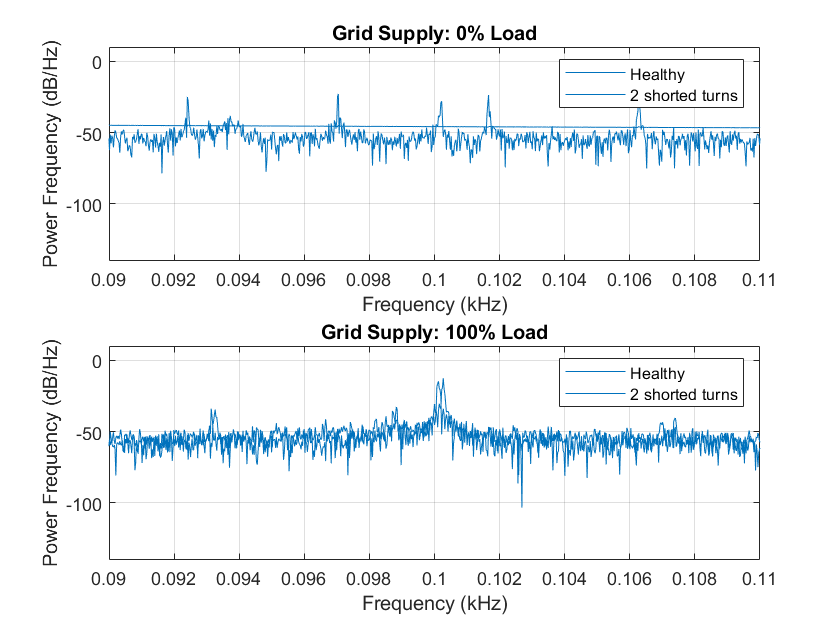

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);
legend('Healthy','2 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 100% Load');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%VibrationMonitoring Inverter-Fed Supply Stator Winding Faults
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%
%2 shorted turns 
%%%%%%%%%%%%%%%%
%%No LOAD
%Healthy No Load
subplot(3,1,1);
nfft = 2^nextpow2(length(nlinvertervibration));
pxx = abs(fft(nlinvertervibration,nfft)).^2/length(nlinvertervibration)/Fs;
maximum = max(pxx)

maximum = 0.0134

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
hold on 

%No Load 2 shorted Fault
nfft = 2^nextpow2(length(invertervibration_fault1_INL1));
pxx = abs(fft(invertervibration_fault1_INL1,nfft)).^2/length(invertervibration_fault1_INL1)/Fs;
maximum = max(pxx)

maximum = 0.0157

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);

hold on

%No Load 4 shorted Fault
nfft = 2^nextpow2(length(invertervibration_fault1_INL2));
pxx = abs(fft(invertervibration_fault1_INL2,nfft)).^2/length(invertervibration_fault1_INL2)/Fs;
maximum = max(pxx)

maximum = 0.0172

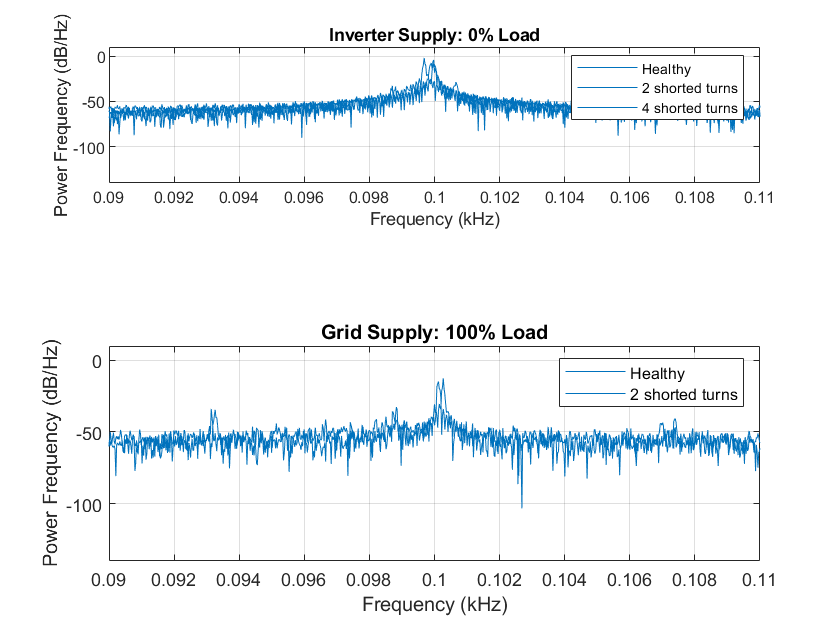

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);
legend('Healthy','2 shorted turns','4 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 0% Load');

hold off


%Healthy Load
subplot(3,1,2);
nfft = 2^nextpow2(length(invertervibration));
pxx = abs(fft(invertervibration,nfft)).^2/length(invertervibration)/Fs;
maximum = max(pxx)

maximum = 0.0172

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
hold on 
%Load 2 shorted Fault
%subplot(3,1,2);
nfft = 2^nextpow2(length(invertervibration_fault1_IL1));
pxx = abs(fft(invertervibration_fault1_IL1,nfft)).^2/length(invertervibration_fault1_IL1)/Fs;
maximum = max(pxx)

maximum = 0.0049

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);

hold on 

%Load 4 shorted Fault
%subplot(3,1,2);
nfft = 2^nextpow2(length(invertervibration_fault1_IL1));
pxx = abs(fft(invertervibration_fault1_IL1,nfft)).^2/length(invertervibration_fault1_IL1)/Fs;
maximum = max(pxx)

maximum = 0.0049

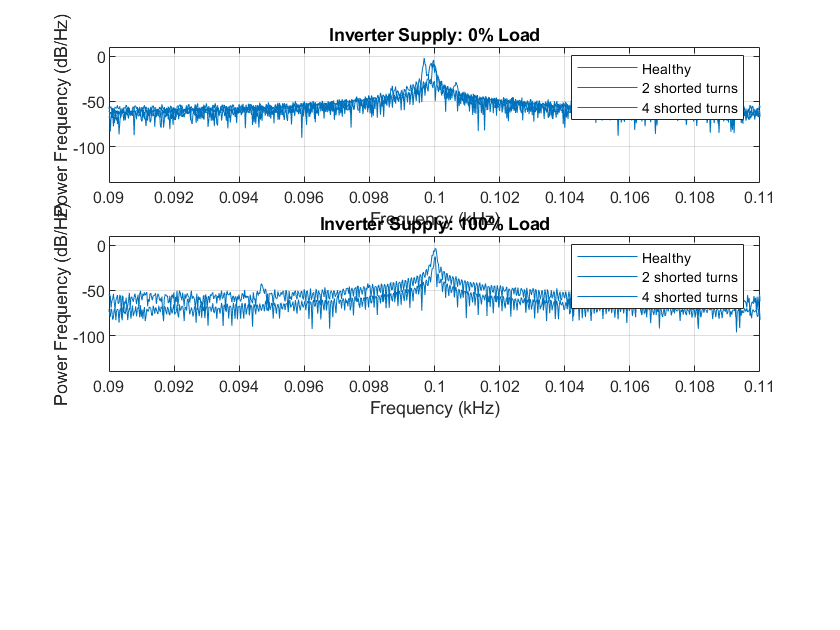

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.090 0.110 -140 10]);
legend('Healthy','2 shorted turns','4 shorted turns');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 100% Load');
hold off


  
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Vibration Monitoring Grid-Fed Supply Broken Rotor Bar Fault 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%NO LOAD
%Healthy No Load
subplot(4,1,1);
nfft = 2^nextpow2(length(nlgridvibration));
pxx = abs(fft(nlgridvibration,nfft)).^2/length(nlgridvibration)/Fs;
maximum = max(pxx)

maximum = 0.0285

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
hold on 

%No Load Fault
nfft = 2^nextpow2(length(gridvibration_fault2_GNL));
pxx = abs(fft(gridvibration_fault2_GNL,nfft)).^2/length(gridvibration_fault2_GNL)/Fs;
maximum = max(pxx)

maximum = 3.3631e-06

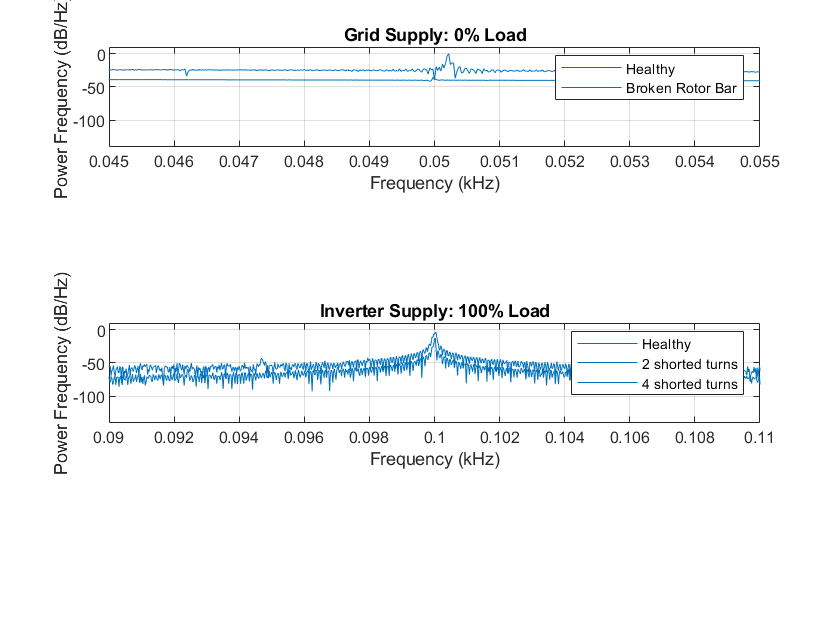

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 0% Load');
hold off


%%LOAD

%Healthy Load
subplot(4,1,2);
nfft = 2^nextpow2(length(gridvibration));
pxx = abs(fft(gridvibration,nfft)).^2/length(gridvibration)/Fs;
maximum = max(pxx)

maximum = 0.0018

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
hold on 

%Load Fault
nfft = 2^nextpow2(length(gridvibration_fault2_GL));
pxx = abs(fft(gridvibration_fault2_GL,nfft)).^2/length(gridvibration_fault2_GL)/Fs;
maximum = max(pxx)

maximum = 5.9463e-04

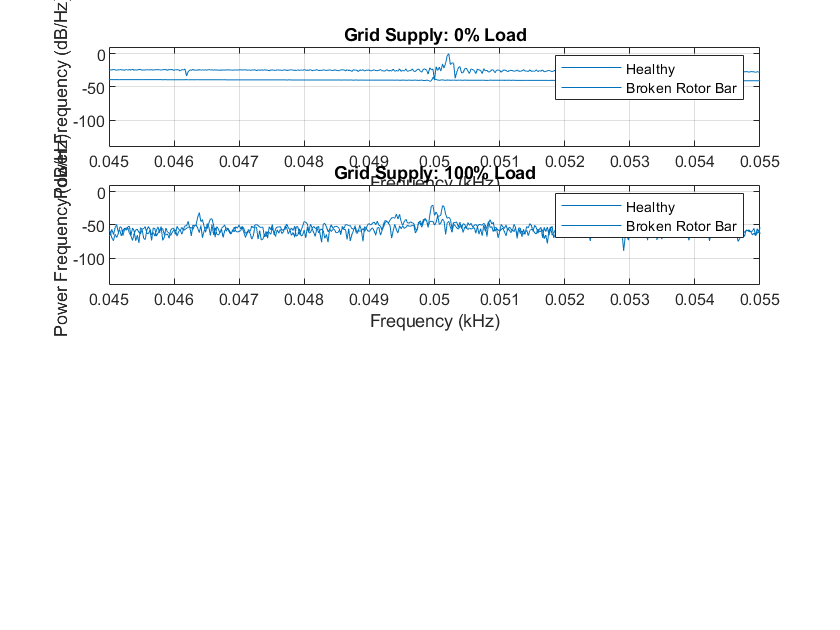

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Grid Supply: 100% Load');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Vibration Monitoring Inverter-Fed Supply Broken Rotor Bar Faults
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%No LOAD
%Healthy No Load
subplot(5,1,1);
nfft = 2^nextpow2(length(nlinvertervibration));
pxx = abs(fft(nlinvertervibration,nfft)).^2/length(nlinvertervibration)/Fs;
maximum = max(pxx)

maximum = 0.0134

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
hold on 

%No Load Broken Rotor Bar Fault
nfft = 2^nextpow2(length(invertervibration_fault2_INL));
pxx = abs(fft(invertervibration_fault2_INL,nfft)).^2/length(invertervibration_fault2_INL)/Fs;
maximum = max(pxx)

maximum = 0.0103

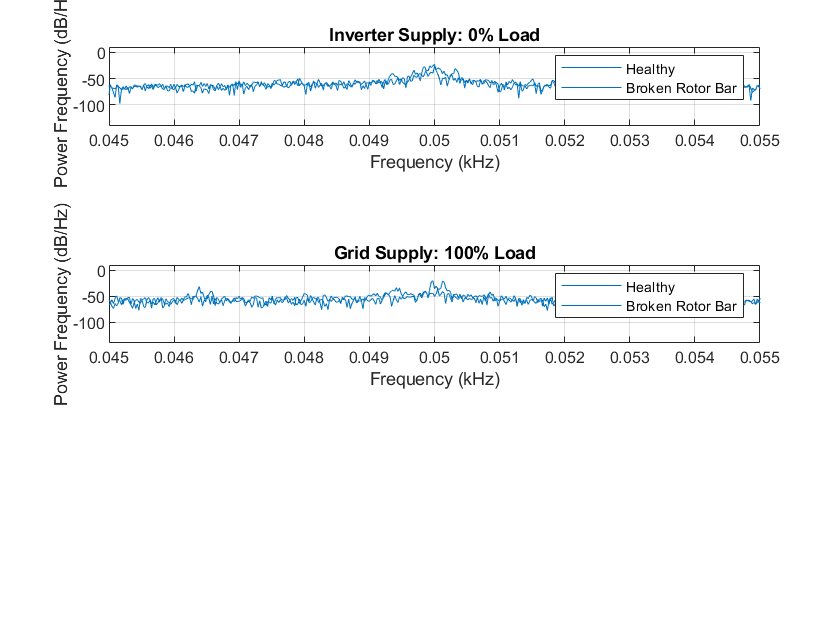

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 0% Load');

hold off


%LOAD

%Healthy Load
subplot(5,1,2);
nfft = 2^nextpow2(length(invertervibration));
pxx = abs(fft(invertervibration,nfft)).^2/length(invertervibration)/Fs;
maximum = max(pxx)

maximum = 0.0172

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);

hold on 

%Load Broken Rotor Bar Fault
nfft = 2^nextpow2(length(invertervibration_fault2_IL));
pxx = abs(fft(invertervibration_fault2_IL,nfft)).^2/length(invertervibration_fault2_IL)/Fs;
maximum = max(pxx)

maximum = 0.0113

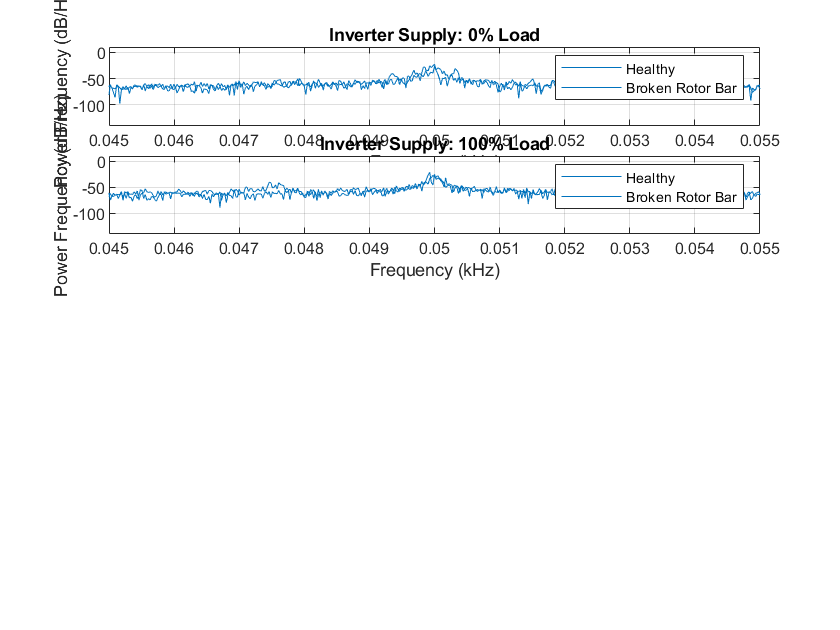

pxx = pxx./maximum;
hpsd = dspdata.psd(pxx(1:length(pxx)/2),'Fs',Fs);
plot(hpsd);
axis([0.045 0.055 -140 10]);
legend('Healthy','Broken Rotor Bar');
ylabel('Power Frequency (dB/Hz)');
xlabel('Frequency (kHz)');
grid on
title('Inverter Supply: 100% Load');
hold off